# Example on how to use TSEMO_V4

Copyright (c) by Eric Bradford, Artur M. Schweidtmann and Alexei Lapkin, 2020-23-05.

## Step 1: Set path to folder

Matlab Home, Set Path, Add folder with subfolders, select "TS-EMO-master" folder

## Step 2: Create function file with multiobjective function to be optimized

In this example we aim to find the Pareto front of "vlmop2", e.g. see vlmop2 for format

f = @runOpt % function that returns the response variable given the X values

f = function_handle with value:
    @runOpt



% Sets filepaths to functions so that they can be used
addpath("C:\Users\eng_adm\OneDrive - University of Leeds\PhD project infomation\Data\Code\MATLAB\HPLC files and code\HPLC GUI optimise versions\V1.3\TS-EMO HPLC optimise");

addpath("C:\Users\eng_adm\OneDrive - University of Leeds\PhD project infomation\Data\Code\MATLAB\HPLC files and code\HPLC GUI optimise versions\V1.3\TS-EMO HPLC optimise\src\file");

addpath("C:\Users\eng_adm\OneDrive - University of Leeds\PhD project infomation\Data\Code\MATLAB\HPLC files and code\HPLC Data\cmtmdHPLC002")

addpath("C:\Users\eng_adm\OneDrive - University of Leeds\PhD project infomation\Data\Code\MATLAB\HPLC files and code\HPLC GUI optimise versions\V1.3\TS-EMO HPLC optimise\PeakFinder")

addpath("C:\Users\eng_adm\OneDrive - University of Leeds\PhD project infomation\Data\Code\MATLAB\HPLC files and code\HPLC GUI optimise versions\V1.3\TS-EMO HPLC optimise\src\preprocessing")


disp ('executing TS-EMO startup script...')

executing TS-EMO startup script...


mydir = fileparts (mfilename ("C:\Users\eng_adm\OneDrive - University of Leeds\PhD project infomation\Data\Code\MATLAB\HPLC files and code\HPLC GUI optimise versions\V1.3\TS-EMO HPLC optimise")); % where am I located
addpath (mydir)
folders = {'Test_functions', 'NGPM_v1.4', 'Mex_files/hypervolume', 'Mex_files/invchol', 'Mex_files/pareto front', 'Direct'}; 
for d = folders, addpath (fullfile (mydir, d{1})), end

% Establish conectin with Excel server
excelapp = actxGetRunningServer('Excel.Application');
wkbk = excelapp.Workbooks;
list = fieldnames(excelapp);
sheets = excelapp.Sheets;
sheet12 = Item(sheets,1);

% Set run opt to true
set(sheet12,'Range','I2', string(1));

## Step 3: Specify problemof hold

no_outputs = 2;               % number of objectives: Rs,crit, numb of peaks and max time
no_inputs  = 3;               % number of decision variables: % OMstart, gradient time, temperature 
lb = [25, 1, 5];                   % define lower bound on decision variables, [lb1,lb2,...]
ub = [60, 10, 50];                 % define upper bound on decision variables, [ub1,ub2,...]
opt = TSEMO_options;             % call options for solver, see TSEMO_options file to adjust
opt.maxeval = 3;                % number of function evaluations before termination
opt.NoOfBachSequential = 1;      % number of function evaluations per iteration

## Step 4: Generate initial dataset

dataset_size = 10;                       % initial dataset size
X = lhsdesign(dataset_size,no_inputs);  % Latin hypercube design
for k = 1:size(X,1)
    X(k,:) = X(k,:).*(ub-lb)+lb;        % adjustment of bounds
end

% Total number of iterations = opt.maxeval/opt.NoOfBachSequential


## Or step 4: Load inital dataset

X = load("startingvars5.mat")
X = X.X
Y = load("responceVars5.mat")
Y = Y.Y

## Step 5: Start algorithm to find Pareto front

[Xpareto,Ypareto,X,Y,XparetoGP,YparetoGP,YparetoGPstd,hypf] = TSEMO_V4(f,X,Y,lb,ub,opt);

% INPUTS
% f denotes the function to be optimized
% X and Y   are the initial datasets to create a surrogate model
% lb and ub are the lower and upper bound of the decision variables
% opt is the option structure of the algorithm

% OUTPUTS
%   Xpareto and Ypareto correspond to the current best Pareto set and Pareto
%   front respectively. 
%   X and Y are the complete dataset of the decision variables and 
%   the objectives respectively. 
%   XparetoGP and YparetoGP represent the Pareto set and Pareto front of the 
%   final Gaussian process model within the algorithm. It is recommended to
%   use these as final result for problems with measurement noise. 
%   YparetoGPstd denotes the standard deviations of the predictions of
%   the GP pareto front YparetoGP  
%   hypf represents the final hyperparameters found for analysis

% For each iteration the current iteration number is displayed, the
% predicted hypervolume improvement and the time taken.

% TS-EMO creates a log file named "TSEMO_log.txt" that contains all relevant information 
% over the entire algorithm run.

% Establish conectin with Excel server
excelapp = actxGetRunningServer('Excel.Application');
wkbk = excelapp.Workbooks;
list = fieldnames(excelapp);
sheets = excelapp.Sheets;
sheet12 = Item(sheets,1);

%Set run opt to false and then turn off HPLC
set(sheet12,'Range','I2', string(0));
SetAndRunHPLC

save responceVars5.mat Y
save startingvars5.mat X
save('workspaceopt2')

## Step 6: Visualise results




dataset_size = 10

dataset_size = 10

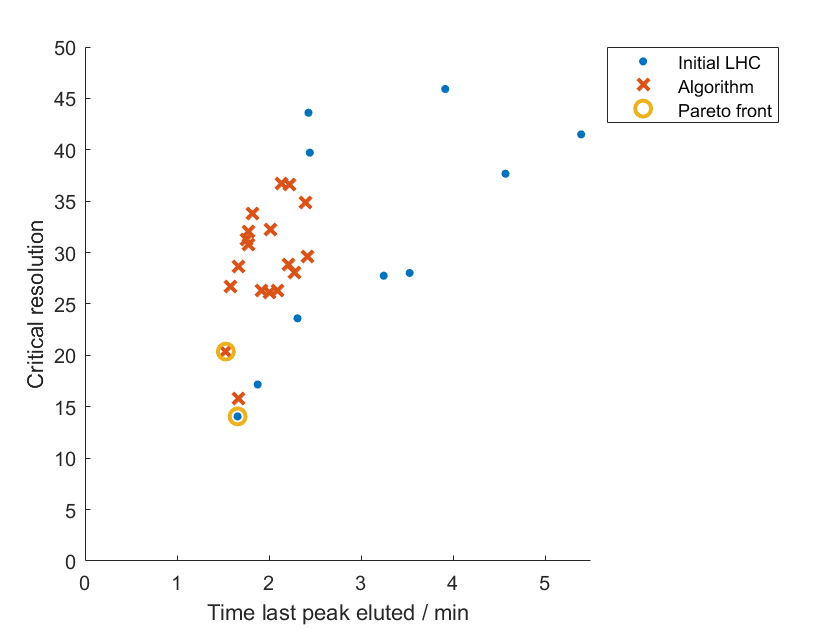

figure
hold on
plot(Y(1:dataset_size,1),Y(1:dataset_size,2),'.','MarkerSize',14)
plot(Y(dataset_size+1:end,1),Y(dataset_size+1:end,2),'x','MarkerSize',8,'LineWidth',2)
plot(Ypareto(:,1),Ypareto(:,2),'O','MarkerSize',8,'LineWidth',2)
%plot(YparetoGP(:,1),YparetoGP(:,2),'x','MarkerSize',8,'LineWidth',2)
%errorbar(YparetoGP(:,1),YparetoGP(:,2),YparetoGPstd(:,2),YparetoGPstd(:,2),YparetoGPstd(:,1),YparetoGPstd(:,1),'O','MarkerSize',8,'LineWidth',0.5)
legend('Initial LHC','Algorithm','Pareto front', "Location","bestoutside")
xlabel('Time last peak eluted / min')
ylabel('Critical resolution')
xlim([0 5.5])
ylim([0 50])
hold off

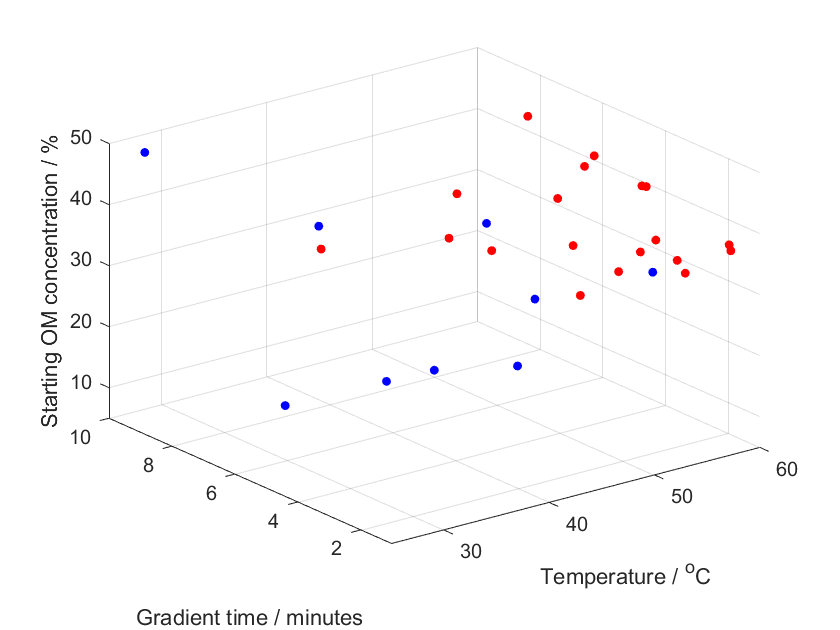



scatter3(X(1:10,1), X(1:10,2), X(1:10,3), 20, "blue", "filled")
hold on
scatter3(X(10:end,1), X(10:end,2), X(10:end,3), 20, "red", "filled")
hold off
xlabel("Temperature / ^oC")
ylabel("Gradient time / minutes")
zlabel("Starting OM concentration / %")
xlim([25 60])
ylim([1 10])
zlim([5 50])